# Question 2

## Part A

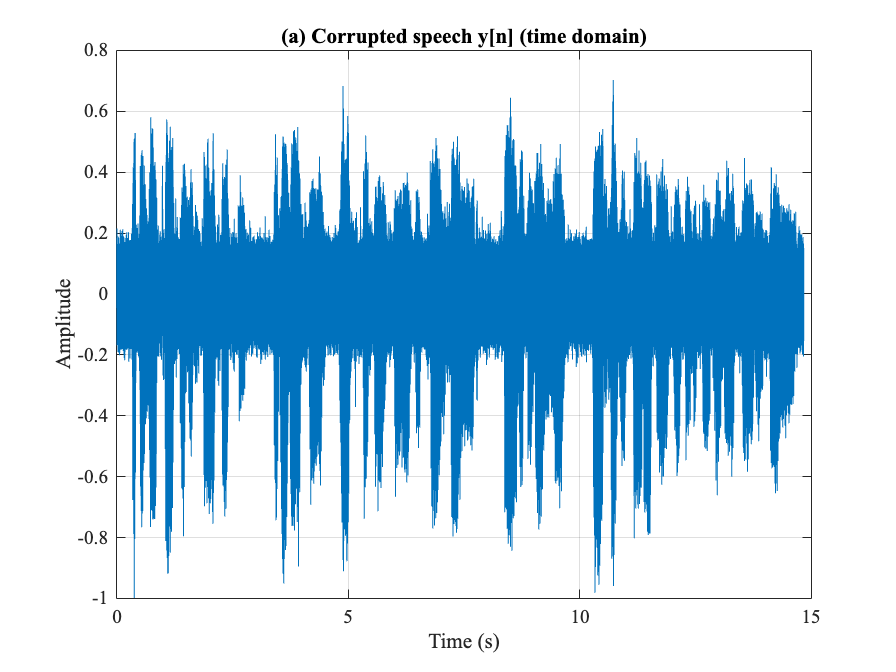

[y, fs] = audioread('corrupted_speech.wav'); 

% If stereo, convert to mono:
if size(y,2) > 1
    y = mean(y,2);
end
N = length(y);
t = (0:N-1)/fs;

figure('Name','Time Domain');
plot(t, y);
xlabel('Time (s)');
ylabel('Amplitude');
title('(a) Corrupted speech y[n] (time domain)');
grid on;

## Part B

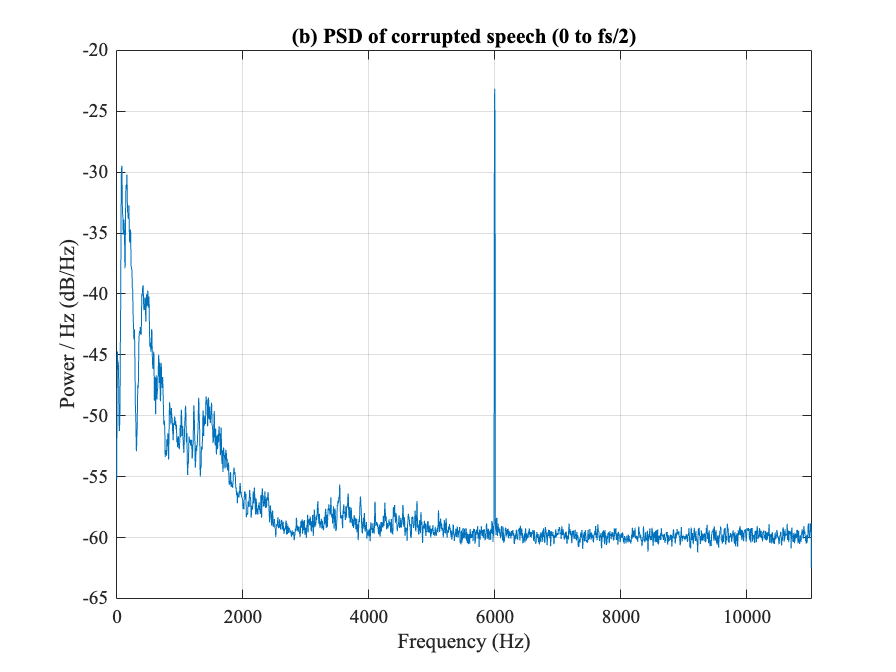

win = hamming(4096);
noverlap = round(0.5*length(win));
nfft = 2^nextpow2(8*length(win)); % fine freq resolution
[Px, f] = pwelch(y, win, noverlap, nfft, fs, 'power'); % power/Hz

% Convert to dB/Hz
Px_dB = 10*log10(Px + eps);

figure('Name','PSD');
plot(f, Px_dB);
xlabel('Frequency (Hz)');
ylabel('Power / Hz (dB/Hz)');
title('(b) PSD of corrupted speech (0 to fs/2)');
xlim([0 fs/2]);
grid on;

## Part C

% Find sharp spike (whine) - look for narrow peak significantly above local floor
% Simple approach: find global maxima in PSD and ensure it's narrowband
[~, idx_max] = max(Px);
f_whine = f(idx_max);

% Also compute approximate speech energy band by cumulative PSD
totalEnergy = trapz(f, Px);
cumEnergy = cumtrapz(f, Px);
frac = cumEnergy / totalEnergy;
% find frequency containing 98% of energy (conservative)
idx98 = find(frac >= 0.98, 1, 'first');
if isempty(idx98)
    f_speech_max = f(end);
else
    f_speech_max = f(idx98);
end

% Hiss: appears as relatively flat elevated noise floor at high freqs in PSD

% Display results
fprintf('Identified whine frequency ~ %.2f Hz (PSD peak).\n', f_whine);

Identified whine frequency ~ 5999.69 Hz (PSD peak).


fprintf('Approx. speech energy mostly below %.2f Hz (98%% energy threshold).\n', f_speech_max);

Approx. speech energy mostly below 7882.50 Hz (98% energy threshold).


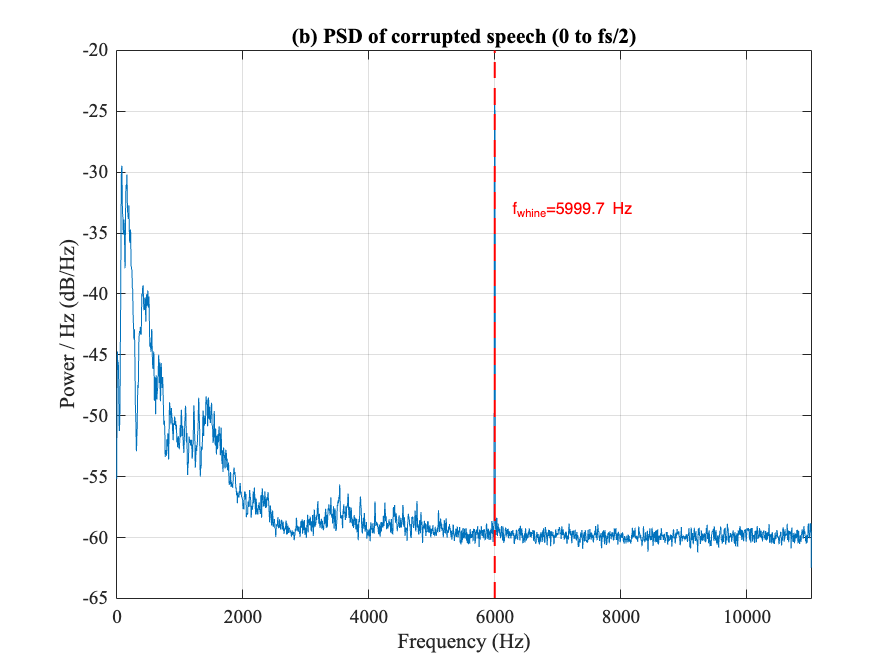


% Mark on PSD plot
hold on;
plot([f_whine f_whine], ylim, '--r', 'LineWidth', 1.2);
text(f_whine, max(Px_dB)-10, sprintf('  f_{whine}=%.1f Hz', f_whine), 'Color','r');

## Part D

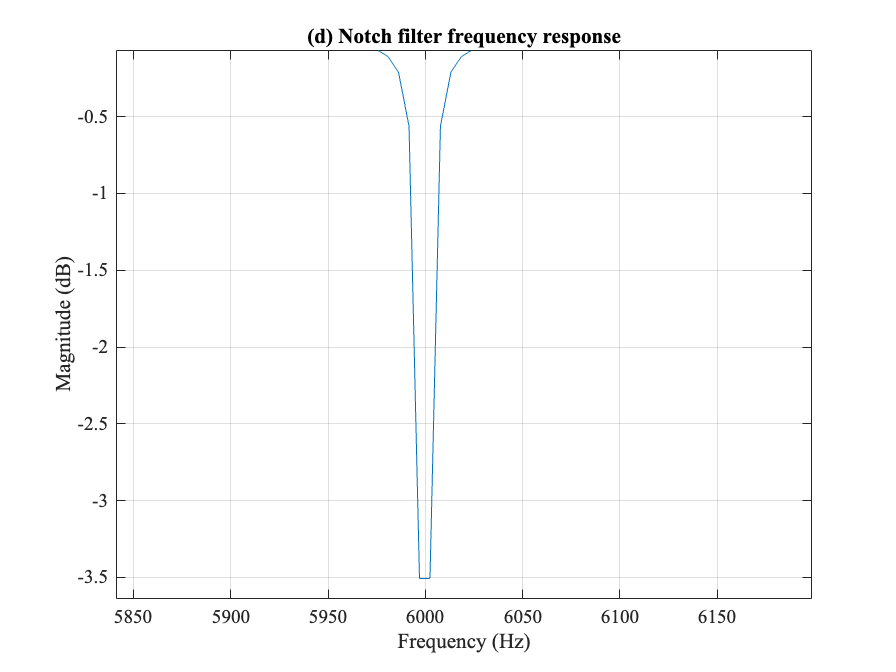

wo = f_whine/(fs/2); % normalized (0..1), center freq for iirnotch uses f0/(fs/2)
% Choose quality factor Q; higher Q = narrower notch. Estimate Q:
Q = 1000; % adjust if needed
[b_notch, a_notch] = iirnotch(wo, wo/Q);

% Apply zero-phase filtering to avoid phase distortionی
ynotched = filtfilt(b_notch, a_notch, y);

% Plot frequency response of notch
[H_notch, w_notch] = freqz(b_notch, a_notch, 2048, fs);
figure('Name','Notch Response');
plot(w_notch, 20*log10(abs(H_notch)));
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('(d) Notch filter frequency response');
xlim([max(0,f_whine-200) min(fs/2, f_whine+200)]);
grid on;

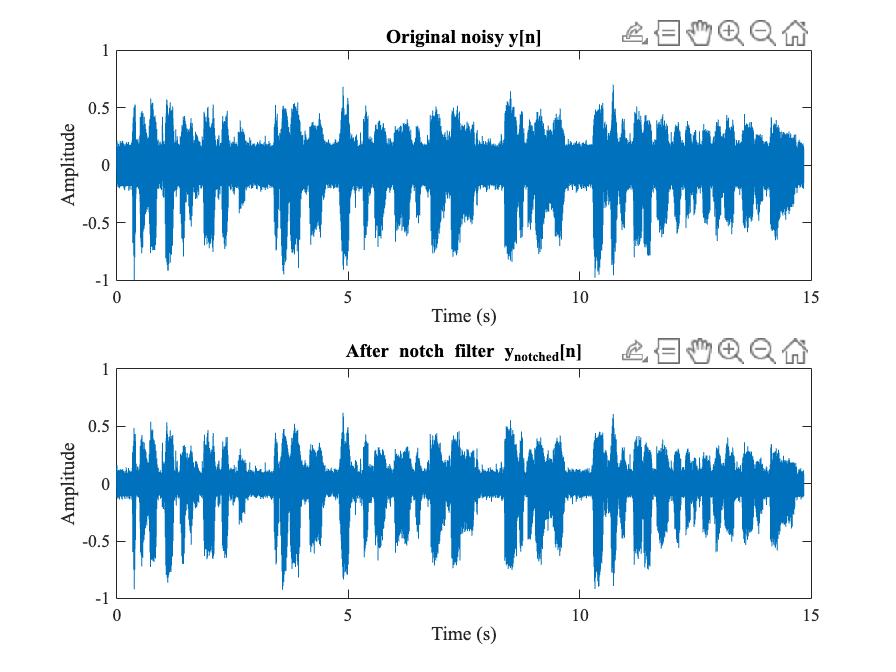


% Plot small time-domain snippet to see effect
figure('Name','Time Domain Before/After Notch');
subplot(2,1,1);
plot(t, y); title('Original noisy y[n]'); xlabel('Time (s)'); ylabel('Amplitude');
subplot(2,1,2);
plot(t, ynotched); title('After notch filter y_{notched}[n]'); xlabel('Time (s)'); ylabel('Amplitude');

## Part E

% Choose cutoff frequency based on speech energy computation above
% Set fcut slightly above f_speech_max (e.g., +5%)
fcut = min(f_speech_max * 1.05, fs/2 * 0.95); % do not exceed Nyquist
fprintf('Chosen LPF cutoff fcut = %.2f Hz\n', fcut);

Chosen LPF cutoff fcut = 8276.62 Hz


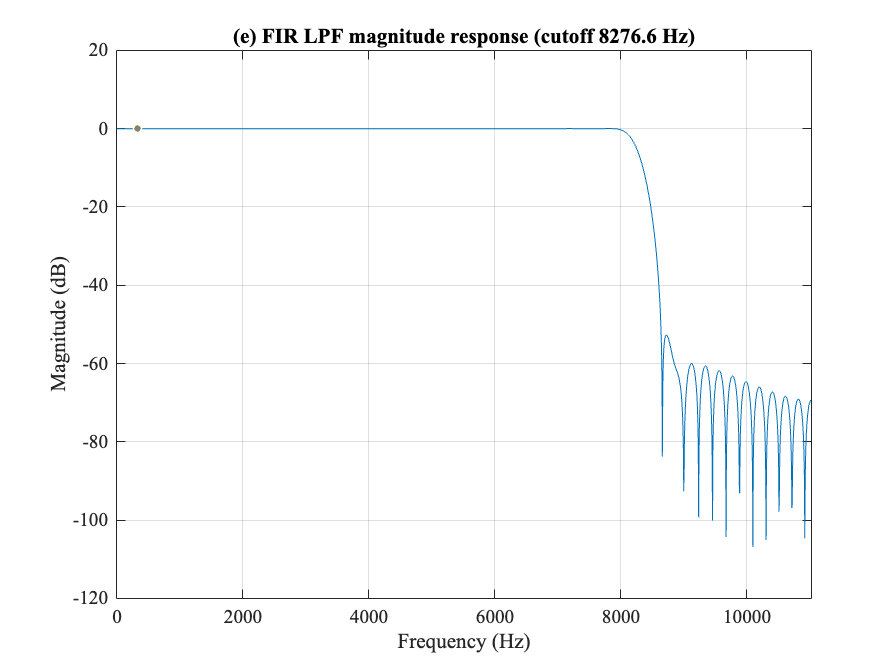


% Design an FIR low-pass filter (e.g., 101 taps for decent transition)
numTaps = 101; % odd recommended
% normalize
Wn = fcut/(fs/2); % normalized cutoff (0..1)
b_lpf = fir1(numTaps-1, Wn, 'low', hamming(numTaps));
% apply zero-phase filtering
z = filtfilt(b_lpf, 1, ynotched);

% Plot LPF freq response
[H_lpf, w_lpf] = freqz(b_lpf, 1, 2048, fs);
figure('Name','LPF Response');
plot(w_lpf, 20*log10(abs(H_lpf)));
xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)');
title(sprintf('(e) FIR LPF magnitude response (cutoff %.1f Hz)', fcut));
xlim([0 fs/2]);
grid on;

## Part F

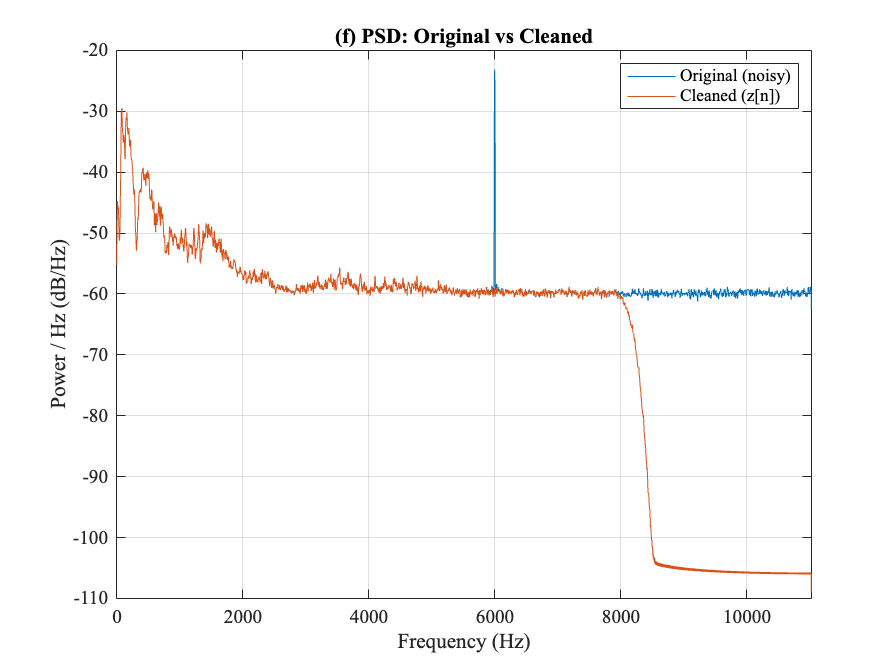

[Px_clean, f_clean] = pwelch(z, win, noverlap, nfft, fs, 'power');
Px_clean_dB = 10*log10(Px_clean + eps);



figure('Name','PSD Comparison');
plot(f, Px_dB, 'DisplayName', 'Original (noisy)');
hold on;
plot(f_clean, Px_clean_dB, 'DisplayName', 'Cleaned (z[n])');
xlabel('Frequency (Hz)');
ylabel('Power / Hz (dB/Hz)');
title('(f) PSD: Original vs Cleaned');
xlim([0 fs/2]);
legend;
grid on;

## Part G

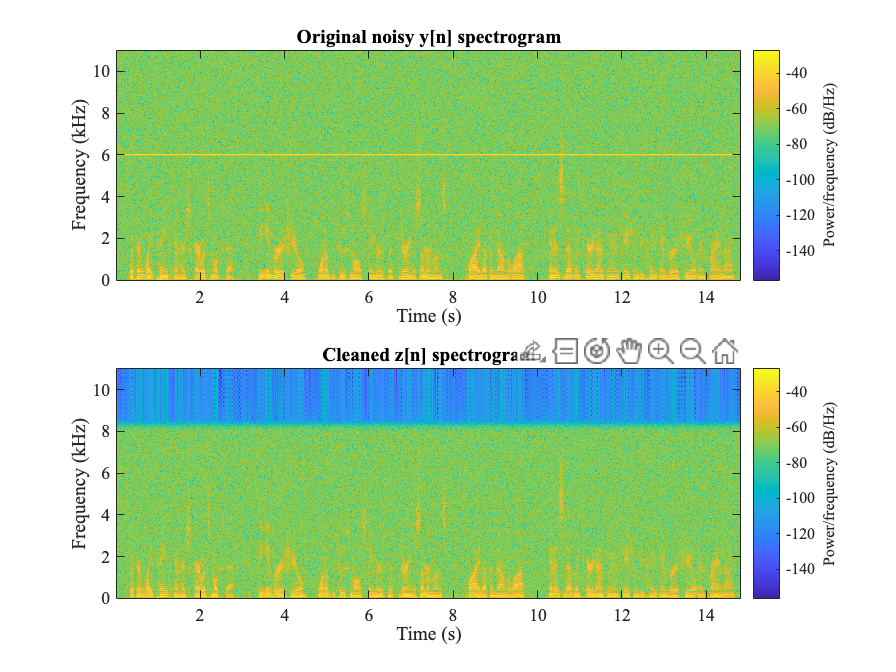

win_spec = 1024;
nover_spec = round(0.75*win_spec);
nfft_spec = 2048;

figure('Name','Spectrograms');
subplot(2,1,1);
spectrogram(y, win_spec, nover_spec, nfft_spec, fs, 'yaxis');
title('Original noisy y[n] spectrogram');
ylim([0 11]); % show up to ~8 kHz (yaxis in kHz)
subplot(2,1,2);
spectrogram(z, win_spec, nover_spec, nfft_spec, fs, 'yaxis');
title('Cleaned z[n] spectrogram');
ylim([0 11]);

## Part H

% Write cleaned audio to file for listening later
audiowrite('corrupted_speech_notched_and_lpf.wav', z, fs);
fprintf('Saved cleaned audio to corrupted_speech_notched_and_lpf.wav\n');

Saved cleaned audio to corrupted_speech_notched_and_lpf.wav
